Source [1] : [https://www.research-collection.ethz.ch/handle/20.500.11850/214143](https://www.research-collection.ethz.ch/handle/20.500.11850/214143)

Source [2] : [https://www.bitcraze.io/products/crazyflie-2-1/](https://www.bitcraze.io/products/crazyflie-2-1/)

## Dimensions

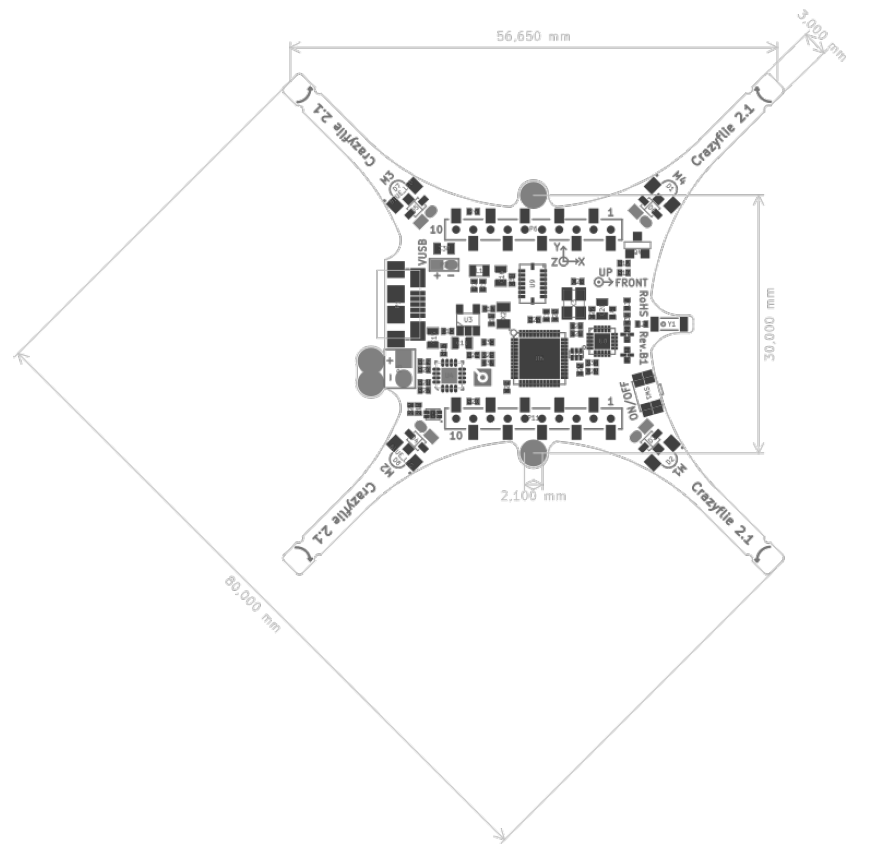

arm_length = 0.040; % assuming that arm_length is half of a diameter
rotor_offset_top = 0.001 ; % some value

## Mass

mass_drone = 0.027;
mass_mocap = 0.009;
mass_total = mass_drone + mass_mocap;

inertia_xx = 16.571710e-6;
inertia_yy = 16.655602e-6;
inertia_zz = 29.261652e-6;

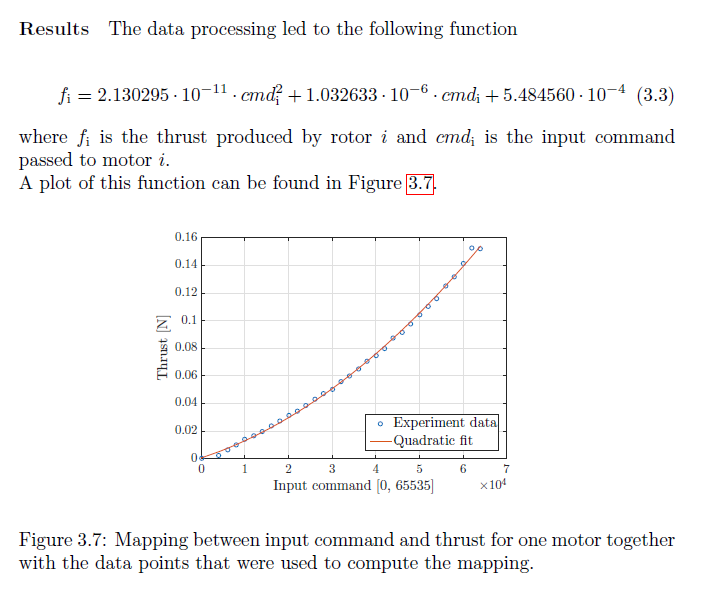

pp0 = 5.484560e-4;
pp1 = 1.032633e-6;
pp2 = 2.130295e-11;
numOfMotors = 4 ; % number of motors

## Mapping according to [1] (Thrust => PWM)

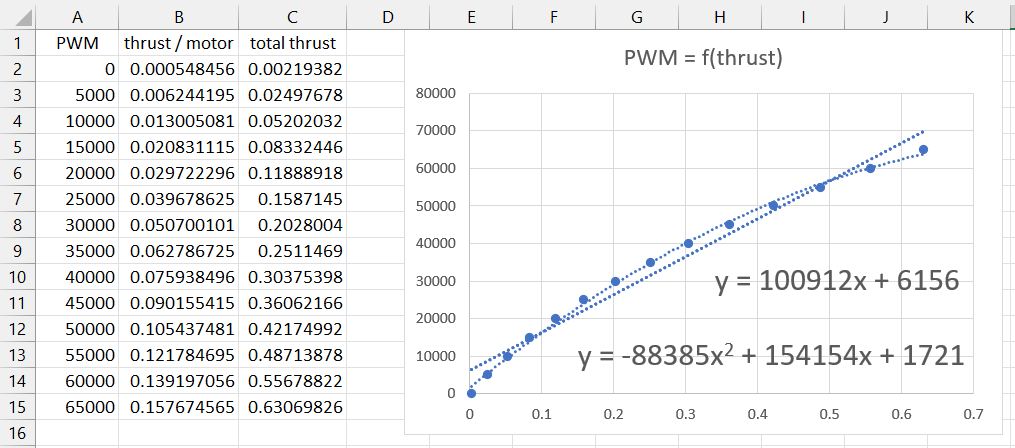

%l0 = 6156;
%l1 = 100912;
%
%p0 = 1721;
%p1 = 154154;
%p2 = -88385;

numOfMotors = 4 ; % number of motors

#### Mapping according to physical testing (Thrust => PWM)

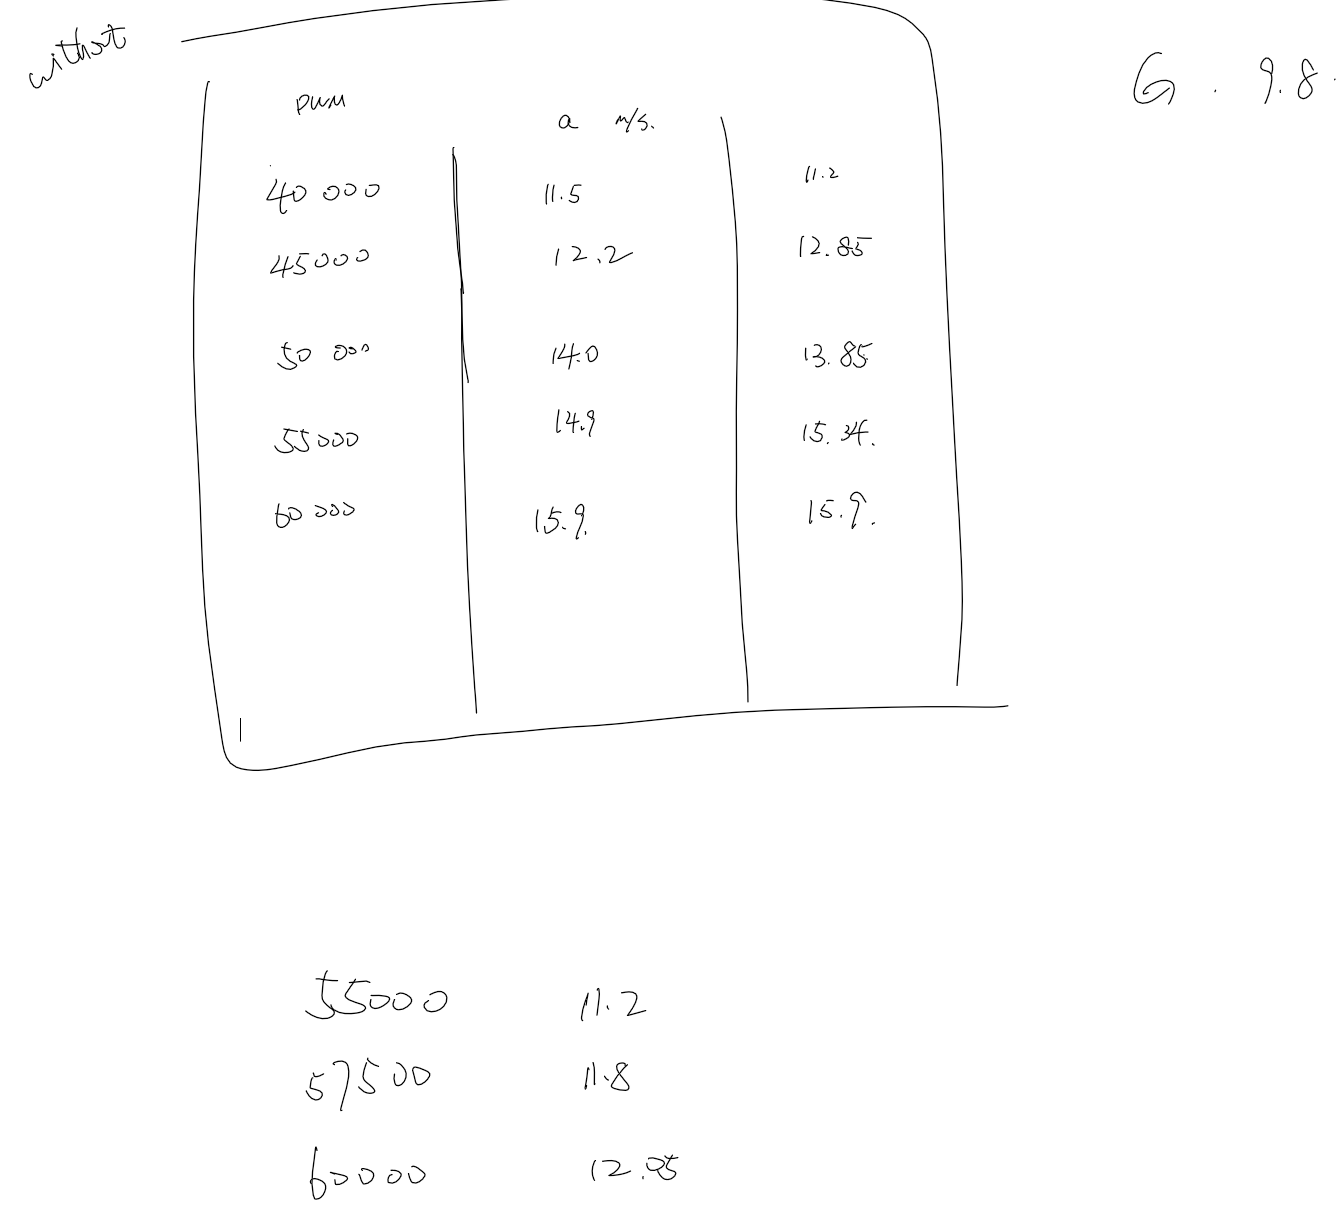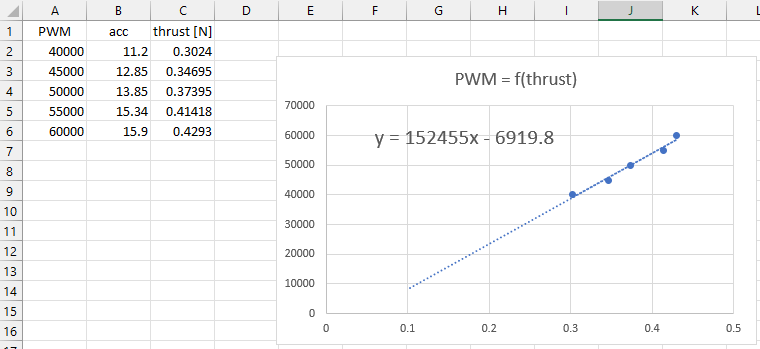

%l0 = 6919.8;
%l1 = 152455;

%l0 = -1700;
%l1 = 136907;

% l0 = -7553;
% l1 = 154500; 15300
l0 = -7600;
l1 = 149000; % 155008

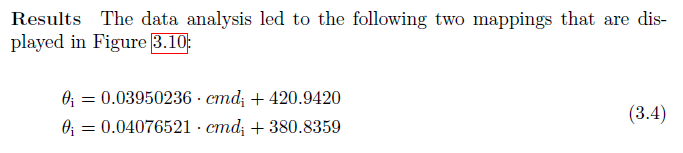

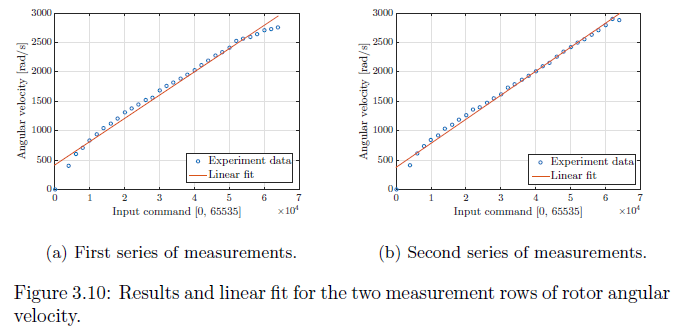

Motor constant is the coefficient between the square of angular velocity of a propellar and the generated thrust. Because in the paper [1] PWM was used as an input for thrust calculation, to graphs need to be compared (Input Cmd -> Thrust & Input Cmd -> Ang. Vel) to determine (Ang. Vel^2 - > Thrust)

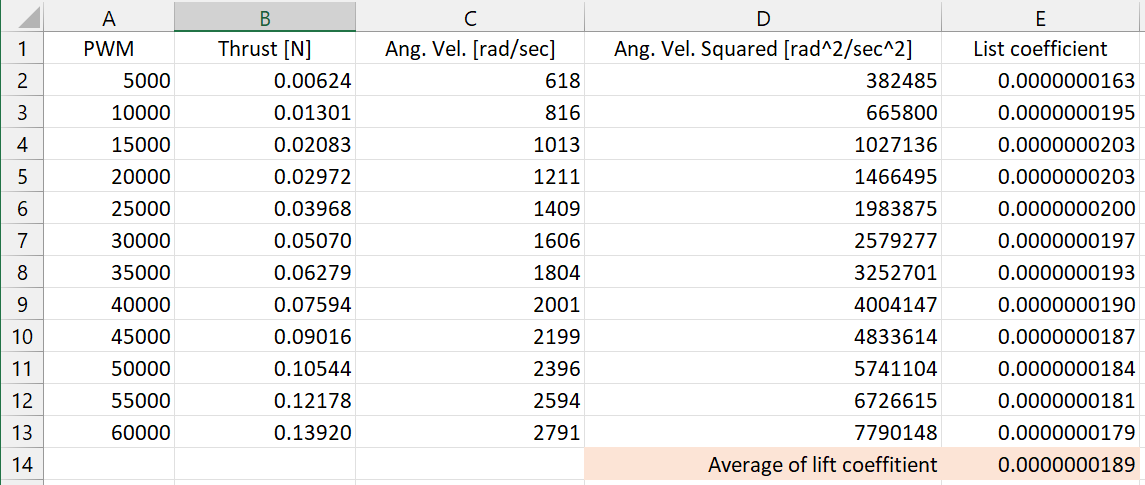

% tmp0 = 420.9420
% tmp1 = 0.03950236
% motor_constant = 8.54858e-06; % previous value
motor_constant = 0.0000000189; % seems really small ???

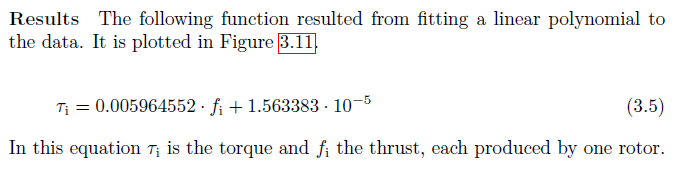

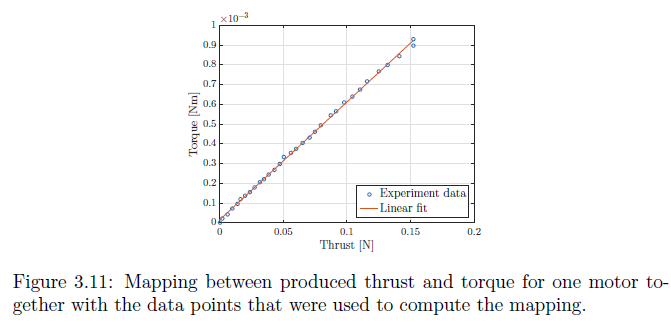

moment_constant = 0.006;

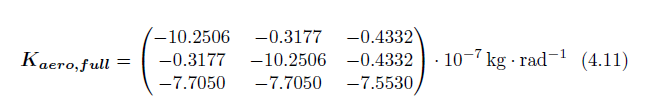

drag_coefficient = 1e-6;
% reference_area = pi * 75e-3^2; % removed from simulation


Also the simulink was simplified (reference_area variable removed from drag)

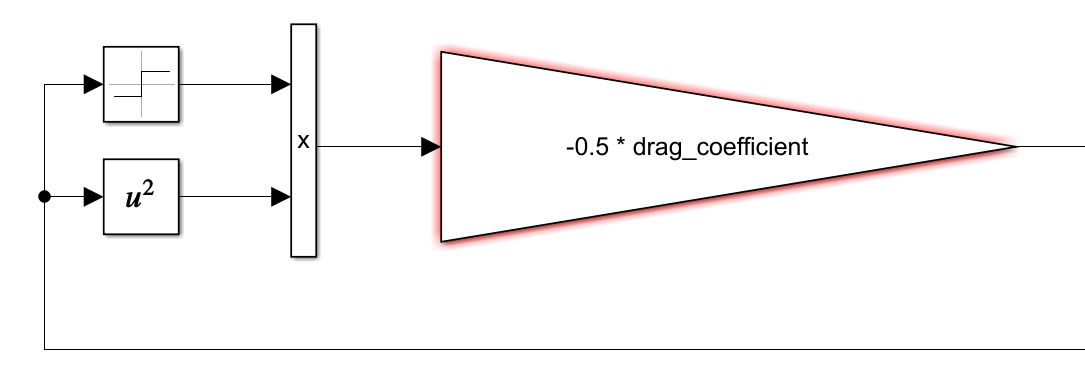

## SIMULATION PARAMETERS CHANGED

x0 = 0;
y0 = 0;
z0 = 0;

max_rot_velocity = 2700;

%mass_drone = 0.68 ;
%mass_total = mass_drone + mass_rod + mass_tip;
%inertia_xx = 0.007 ;
%inertia_yy = 0.007 ;
%inertia_zz = 0.012 ;
%arm_length = 0.17 ;
%rotor_offset_top = 0.01 ;
%drag_coefficient = 0.47;

## SIMULATION PARAMETERS UNCHANGED

route = [0 0 1 ; 9 0 1 ; 9 9 1];
wall_color = [0.8 0.2 0.2];
sample_time = 4e-2;
publish_rate = 1 * sample_time;

g = 9.80665 ;


allocation_matrix = ...
    [1 1 1 1
     0 arm_length 0 -arm_length
     -arm_length 0 arm_length 0
     -moment_constant moment_constant -moment_constant moment_constant] ;

mix_matrix = inv(motor_constant * allocation_matrix) ;
air_density = 1.2041;

%mass_rod = 0.0;
%mass_tip = 0;
%stiffness_rod = 100 ;
%critical_damping_rod = 2 * sqrt(mass_total * stiffness_rod) ;
%stiffness_wall = 100 ;
%critical_damping_wall = 2 * sqrt(mass_total * stiffness_wall) ;

# Other

simTime = 20;

# Attitude PID

% attitude PD
att_Kp  = 0.1; % proportional gain
att_Ki  = 0;    % integral gain
att_Kd  = 10;   % derivative gain
att_N   = 50;  % cut-off frequency

% attitude PID - backup
%att_Kp  = 10; % proportional gain
%att_Ki  = 0.1;    % integral gain
%att_Kd  = 30;   % derivative gain
%att_N   = 50;  % cut-off frequency

# Position PID

% position PID
%pos_Kp  = 9.5; % proportional gain
%pos_Ki  = 0;    % integral gain
%pos_Kd  = 4.5;   % derivative gain
%pos_N   = 25;  % cut-off frequency
%pos_sat = 5; % saturation -
%pos_Kvel = 0;

% position PID - critically damped
pos_Kp  = 0.33; % proportional gain
pos_Ki  = 0.000033;    % integral gain
%pos_Kd  = 0.3;   % derivative gain
pos_N   = 25;  % cut-off frequency
pos_sat = 0.15; % saturation -

% velocity - D
pos_Kvel = 0.25;

% x - PID
posx_Kp  = 0.120; % proportional gain
posx_Ki  = 0.002;    % integral gain
posx_Kd  = 0.150;   % derivative gain
pos_N   = 25;  % cut-off frequency

% y - PID
posy_Kp  = 0.120; % proportional gain
posy_Ki  = 0.002;    % integral gain
posy_Kd  = 0.150;   % derivative gain
posy_N   = 25;  % cut-off frequency

% z - PID
posz_Kp  = 0.100; % proportional gain
posz_Ki  = 0.002;    % integral gain
posz_Kd  = 0.150;   % derivative gain
posz_N   = 25;  % cut-off frequency



%pos_Kp  = 6; % proportional gain
%pos_Ki  = 0;    % integral gain
%pos_Kd  = 3.60;   % derivative gain
%pos_N   = 25;  % cut-off frequency
%pos_sat = 5; % saturation -
%pos_Kvel = 0;

% position PID - backup 2
%pos_Kp  = 11.5; % proportional gain
%pos_Ki  = 0;    % integral gain
%pos_Kd  = 5;   % derivative gain
%pos_N   = 25;  % cut-off frequency
%pos_sat = 5; % saturation -
%pos_Kvel = 0;